%% analysis code for PRS data(cos7 data under different kinds of Fatty Acid 
% treatment). 

clear all;clc;

% load the Raman spectra, phase image and Lds information obtained from U-net 
% recognition algorithm.
load('Data_cos7FA.mat');

x = 255:955;
pxpx = [423 438 502 663 742.5 754];
wnpx = [1001.4 1031.8 1155.3 1450.5 1583.1 1602.3];
wn = polyval(polyfit(pxpx,wnpx,2),1:1024); 

% remove the signal that is too low to be processed.
for ii = 1: size(ldsSpec0,2)
    if(max(ldsSpec0(:,ii))<=200)
        Index0(ii,8) = 1;
    end
end

idtemp = 1;
ldsSpec1 = ldsSpec0(:,Index0(:,8)==0)';
Index1 = Index0(Index0(:,8)==0,:);
ldsSpec1 = ldsSpec1./sum(ldsSpec1,2);

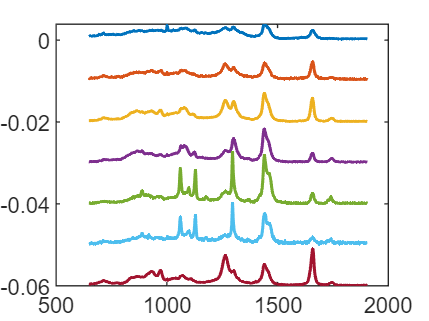

%% remove comsic ray
err0 = [11960,2620,6225,6256,9392,221,3938,5227,4910,12505,...
    12775,4066,6325,10523,539,999,13244,12599,10444,6255,...
    1430,10037,1521,8842,1993,1081,8440,5078,313,6838,6839,...
    8731,8746,8073,2519,7993,7504,11315,12544,1686,6772,11719,...
    1433,2175,6259,110,8888,5152,4901,4720,5994,9010,9517,...
    11366,5830,5556,6942,5238,11886,1841,9109,5283,9339];
for ii = 1:size(err0,2)
    Index1(err0(ii),8) = 1;
end
lds1temp = ldsSpec1(Index1(:,8) == 0,:);
idtemp = 1;
for ii = 1: size(ldsSpec1,1)
    if(Index1(ii,8)==0)
        idt(idtemp) = ii;
        idtemp = idtemp + 1;
    end
end

%% use HCV analysis to remove error points
maxclusts = 7;
Z = linkage(lds1temp,'average');
% dendrogram(Z);
T = cluster(Z,'maxclust',maxclusts);
ztemp = 0;
figure
for ii = 1:maxclusts
%     idt(find(T==ii))
    plot(wn(x),mean(lds1temp(T == ii,:),1)-0.01*ztemp,'LineWidth',1.2);
    hold on;
    ztemp = ztemp + 1;
end

ldsSpec2 = lds1temp;
Index2 = Index1(Index1(:,8) == 0,:);


ldsSpec4 = ldsSpec2(T ~= 1,:);
Index3 = Index2(T ~= 1,:);

% load LDs' spectra after HybrifPCA denoised.
load('spect50x.mat')
ldsSpec3 = Reconstructed(1:13178,:);
ldsSpec3 = ldsSpec3./sum(ldsSpec3,2);

% PCA analysis of LDs spectra.
[c,s,score] = pca(ldsSpec3);
sum(score(1:6))/sum(score)

ans = 0.9660

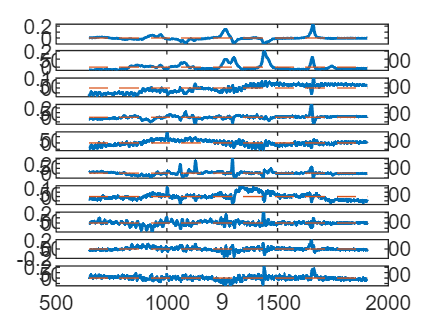


figure
for ii = 1:10
    subplot(10,1,ii)
    plot(wn(x),c(:,ii + 0),'LineWidth',1.2),xlabel(num2str(ii));
    hold on
    plot(wn(x),zeros(length(x),1),'--','LineWidth',0.5)
end

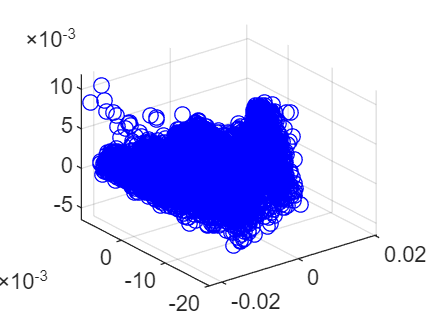


figure
plot3(s(:,1),s(:,2),s(:,3),'bo');
grid on

% VCA analysis.
endme = 5;
A_est = vca(ldsSpec3','endmembers',endme);

SNR estimated = 27.6358[dB]
... Select proj. to p-1


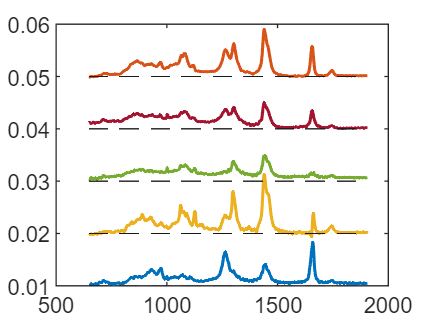

figure
for ii = 1:endme
    plot(wn(x),A_est(:,ii)+0.01*ii,'LineWidth',1.2);
    hold on;
    plot(wn(x),zeros(length(x),1)+0.01*ii,'--','LineWidth',0.2,'Color',[0.1,0.1,0.1]);
    hold on;
end

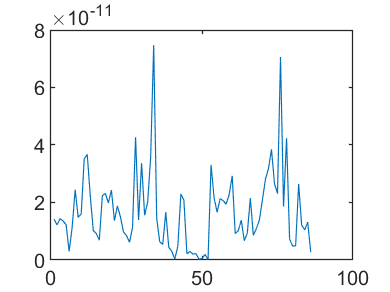

% calculate the Lds' mean diameter, number and total volume per cells.
ldsV = zeros(size(Img,2),1);
ldsN = zeros(size(Img,2),1);
for ii = 1: size(Index3,1)
    Index3(:,17) = 2*sqrt(Index3(:,5)/3.141592654)*54.16;
    Index3(:,16) = (Index3(:,5)*(54.17e-9)^2).^1.5 * 4/3 / sqrt(3.141592654)*1e6;
end
for ii = 1:size(Img,2)
    ldsV(ii) = sum(Index3(Index3(:,11)==ii,16),'all');
    ldsN(ii) = length(find(Index3(:,11)==ii));
    ldsS(ii,1) = mean(Index3(Index3(:,11)==ii,17),'all')/1000;
end


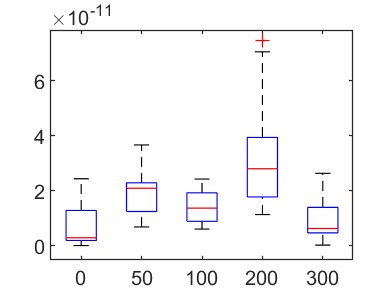


vf = [0*ones(8,1);50*ones(10,1);100*ones(8,1);200*ones(9,1);300*ones(9,1);...
    0*ones(8,1);50*ones(10,1);100*ones(8,1);200*ones(8,1);300*ones(8,1)];
figure
boxplot(ldsV,vf)

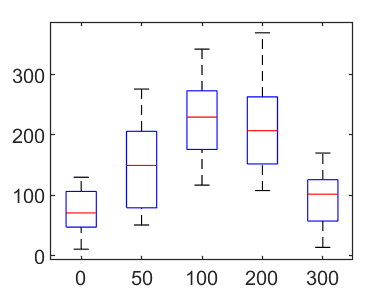

figure
boxplot(ldsN,vf)

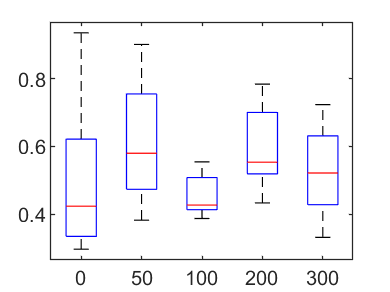

figure
boxplot(ldsS,vf)

vf1 = [1*ones(8,1);2*ones(10,1);3*ones(8,1);4*ones(9,1);5*ones(9,1);...
    1*ones(8,1);2*ones(10,1);3*ones(8,1);4*ones(8,1);5*ones(8,1)];

ldsN1 = ldsN; LdsV1 = ldsV; ldsS1 = ldsS;
save('lds1.mat',"ldsS1","LdsV1","ldsN1","vf1");

ldv1 = 	1.0e+-10 *

    0.1318    0.1894    0.1726    0.2241    0.0723


ldv1 = [mean(ldsV(1:8)),mean(ldsV(9:16)),mean(ldsV(17:25)),mean(ldsV(26:33)),mean(ldsV(35:41))]

%% write the calculation results into the csv file.
abc = ["A","B","C","D","E","F","G",...
        "H","I","J","K","L","M","N","O",...
        "P","Q","R","S","T","U","V","W","X",...
        "Y","Z","AA","AB","AC","AD","AE","AF","AG",...
        "AH","AI","AJ","AK","AL","AM","AN","AO",...
        "AP","AQ","AR","AS","AT","AU","AV","AW","AX","AY","AZ",...
        "BA","BB","BC","BD","BE","BF","BG",...
        "BH","BI","BJ","BK","BL","BM","BN","BO",...
        "BP","BQ","BR","BS","BT","BU","BV","BW","BX","BY","BZ"
        ];
warning off
writematrix(ldsV(vf==0),'m.xls','Sheet',1,'range',strcat(abc(1),'1'));
writematrix(ldsV(vf==50),'m.xls','Sheet',1,'range',strcat(abc(2),'1'));
writematrix(ldsV(vf==100),'m.xls','Sheet',1,'range',strcat(abc(3),'1'));
writematrix(ldsV(vf==200),'m.xls','Sheet',1,'range',strcat(abc(4),'1'));
writematrix(ldsV(vf==300),'m.xls','Sheet',1,'range',strcat(abc(5),'1'));

writematrix(ldsN(vf==0),'m.xls','Sheet',1,'range',strcat(abc(6),'1'));
writematrix(ldsN(vf==50),'m.xls','Sheet',1,'range',strcat(abc(7),'1'));
writematrix(ldsN(vf==100),'m.xls','Sheet',1,'range',strcat(abc(8),'1'));
writematrix(ldsN(vf==200),'m.xls','Sheet',1,'range',strcat(abc(9),'1'));
writematrix(ldsN(vf==300),'m.xls','Sheet',1,'range',strcat(abc(10),'1'));

writematrix(ldsV(vf==0)./ldsN(vf==0),'m.xls','Sheet',1,'range',strcat(abc(11),'1'));
writematrix(ldsV(vf==50)./ldsN(vf==50),'m.xls','Sheet',1,'range',strcat(abc(12),'1'));
writematrix(ldsV(vf==100)./ldsN(vf==100),'m.xls','Sheet',1,'range',strcat(abc(13),'1'));
writematrix(ldsV(vf==200)./ldsN(vf==200),'m.xls','Sheet',1,'range',strcat(abc(14),'1'));
writematrix(ldsV(vf==300)./ldsN(vf==300),'m.xls','Sheet',1,'range',strcat(abc(15),'1'));

writematrix(Index3(Index3(:,9)==200,16),'ml.xls','Sheet',1,'range',strcat(abc(1),'1'));
writematrix(Index3(Index3(:,9)==201,16),'ml.xls','Sheet',1,'range',strcat(abc(2),'1'));
writematrix(Index3(Index3(:,9)==202,16),'ml.xls','Sheet',1,'range',strcat(abc(3),'1'));
writematrix(Index3(Index3(:,9)==203,16),'ml.xls','Sheet',1,'range',strcat(abc(4),'1'));
writematrix(Index3(Index3(:,9)==204,16),'ml.xls','Sheet',1,'range',strcat(abc(5),'1'));
warning on

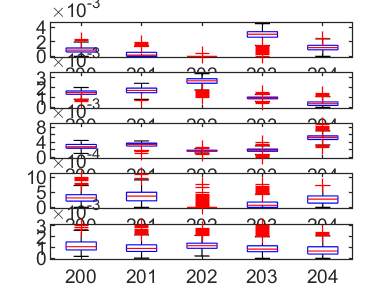

% use NNLS to do spectra fitting.

load('FatAcid_n.mat');
PureFA = [MOA1,MAA1,MPA1,MLA1,mypoly(1,length(x))',-1*mypoly(1,length(x))'];
for ii = 1:size(ldsSpec3,1)
    xasFA(ii,:) = lsqnonneg(PureFA,ldsSpec3(ii,:)');
end
AbgFA = PureFA*xasFA';
ldsSpecFA = ldsSpec3' - AbgFA;


figure
subplot(5,1,1)
boxplot(xasFA(:,1),Index3(:,9))
subplot(5,1,2)
boxplot(xasFA(:,2),Index3(:,9))
subplot(5,1,3)
boxplot(xasFA(:,3),Index3(:,9))
subplot(5,1,4)
boxplot(xasFA(:,4),Index3(:,9))
subplot(5,1,5)
boxplot(xasFA(:,5),Index3(:,9));

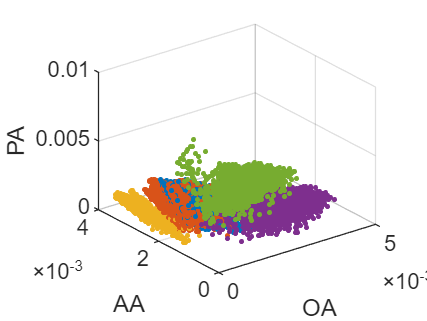

%% the FA concentration distribution。
figure
scatter3(xasFA(Index3(:,9)==200,1),xasFA(Index3(:,9)==200,2),...
    xasFA(Index3(:,9)==200,3),'.')
hold on;
scatter3(xasFA(Index3(:,9)==201,1),xasFA(Index3(:,9)==201,2),...
    xasFA(Index3(:,9)==201,3),'.')
hold on;
scatter3(xasFA(Index3(:,9)==202,1),xasFA(Index3(:,9)==202,2),...
    xasFA(Index3(:,9)==202,3),'.')
hold on;
scatter3(xasFA(Index3(:,9)==203,1),xasFA(Index3(:,9)==203,2),...
    xasFA(Index3(:,9)==203,3),'.')
hold on;
scatter3(xasFA(Index3(:,9)==204,1),xasFA(Index3(:,9)==204,2),...
    xasFA(Index3(:,9)==204,3),'.')

xlabel('OA')
ylabel('AA')
zlabel('PA')

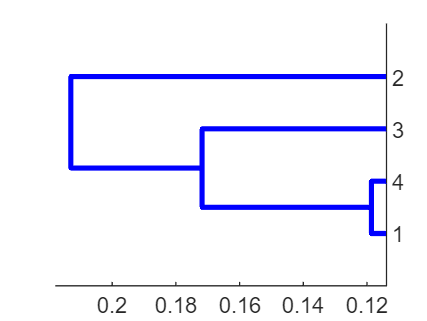

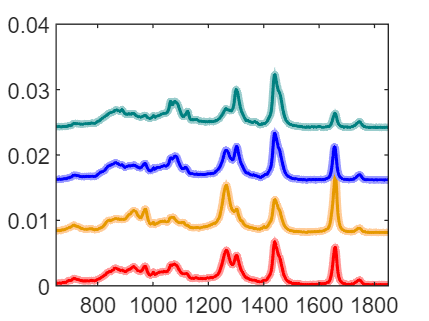


Index3c = Index3; Index3c(:,9) = Index3c(:,9) - 000;ldsSpec3c = ldsSpec3;xasc = xasFA;
% save("cosfa_I.mat","Index3c","ldsSpec3c","xasc");


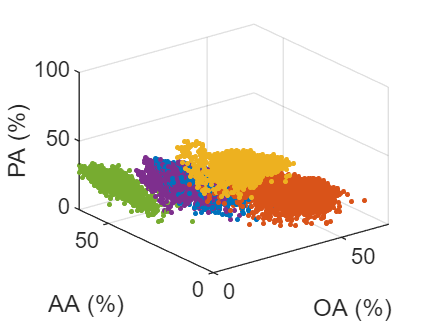

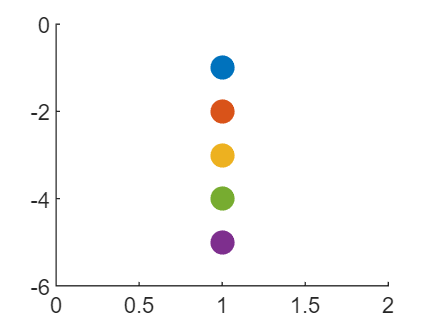

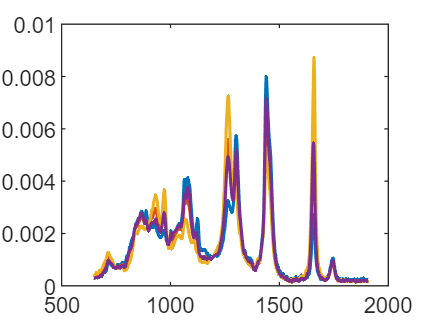

y =            0        3065           0          10
           0          10        3657           0
           0         113           0        3548
        1606           2           0           0
           0        1072           0          95


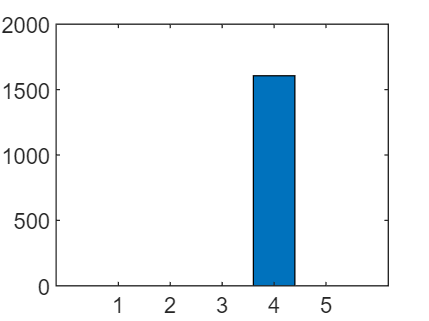

xasFA1 = xasFA./sum(xasFA(:,1:6),2);
figure
scatter3(100*xasFA1(Index3(:,9) == 200,1),100*xasFA1(Index3(:,9)...
    == 200,2),100*xasFA1(Index3(:,9) == 200,3),'.')
hold on;
scatter3(100*xasFA1(Index3(:,9) == 203,1),100*xasFA1(Index3(:,9)...
    == 203,2),100*xasFA1(Index3(:,9) == 203,3),'.')
hold on;
scatter3(100*xasFA1(Index3(:,9) == 204,1),100*xasFA1(Index3(:,9)...
    == 204,2),100*xasFA1(Index3(:,9) == 204,3),'.')
hold on;
scatter3(100*xasFA1(Index3(:,9) == 201,1),100*xasFA1(Index3(:,9)...
    == 201,2),100*xasFA1(Index3(:,9) == 201,3),'.')
hold on;
scatter3(100*xasFA1(Index3(:,9) == 202,1),100*xasFA1(Index3(:,9)...
    == 202,2),100*xasFA1(Index3(:,9) == 202,3),'.')
% hold on;
% scatter3(xasFA(T==4,1),xasFA(T==4,2),xasFA(T==4,3),'.')


xlabel('OA (%)')
ylabel('AA (%)')
zlabel('PA (%)')

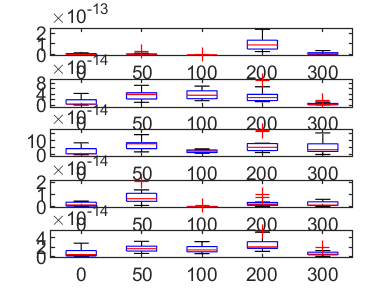

ldsc(1,:) = mean(xasFA(Index3(:,9) == 200,:),1);
ldsc(2,:) = mean(xasFA(Index3(:,9) == 201,:),1);
ldsc(3,:) = mean(xasFA(Index3(:,9) == 202,:),1);
ldsc(4,:) = mean(xasFA(Index3(:,9) == 203,:),1);
ldsc(5,:) = mean(xasFA(Index3(:,9) == 204,:),1);

ldsc = ldsc./sum(ldsc(:,1:4),2);

ldsSpecMean(1,:) = mean(ldsSpec3(Index3(:,9) == 200,:),1);
ldsSpecMean(2,:) = mean(ldsSpec3(Index3(:,9) == 201,:),1);
ldsSpecMean(3,:) = mean(ldsSpec3(Index3(:,9) == 202,:),1);
ldsSpecMean(4,:) = mean(ldsSpec3(Index3(:,9) == 203,:),1);
ldsSpecMean(5,:) = mean(ldsSpec3(Index3(:,9) == 204,:),1);

% write the calculation results of LDs' FA concentration into the csv file.
xasFAcsv = xasFA(:,:);
for iip = 1:5
    writematrix(xasFAcsv(Index3(:,9) == 200,iip)./...
        sum(xasFAcsv(Index3(:,9) == 200, 1:4),2),'fa_f.xls','Sheet',1,'range',strcat(abc(1+iip-1),'1'));
    writematrix(xasFAcsv(Index3(:,9) == 204,iip)./...
        sum(xasFAcsv(Index3(:,9) == 204, 1:4),2),'fa_f.xls','Sheet',1,'range',strcat(abc(6+iip-1),'1'));
    writematrix(xasFAcsv(Index3(:,9) == 202,iip)./...
        sum(xasFAcsv(Index3(:,9) == 202, 1:4),2),'fa_f.xls','Sheet',1,'range',strcat(abc(11+iip-1),'1'));
    writematrix(xasFAcsv(Index3(:,9) == 203,iip)./...
        sum(xasFAcsv(Index3(:,9) == 203, 1:4),2),'fa_f.xls','Sheet',1,'range',strcat(abc(16+iip-1),'1'));
    writematrix(xasFAcsv(Index3(:,9) == 201,iip)./...
        sum(xasFAcsv(Index3(:,9) == 201, 1:4),2),'fa_f.xls','Sheet',1,'range',strcat(abc(21+iip-1),'1'));
end
warning on

% mean FA concentration of LDs under different treatment type.
ldsc1(1,:) = mean(xasFAcsv(Index3(:,9) == 200,:)./...
    sum(xasFAcsv(Index3(:,9) == 200, 1:4),2),1);
ldsc1(2,:) = mean(xasFAcsv(Index3(:,9) == 204,:)./...
    sum(xasFAcsv(Index3(:,9) == 204, 1:4),2),1);
ldsc1(3,:) = mean(xasFAcsv(Index3(:,9) == 202,:)./...
    sum(xasFAcsv(Index3(:,9) == 202, 1:4),2),1);
ldsc1(4,:) = mean(xasFAcsv(Index3(:,9) == 203,:)./...
    sum(xasFAcsv(Index3(:,9) == 203, 1:4),2),1);
ldsc1(5,:) = mean(xasFAcsv(Index3(:,9) == 201,:)./...
    sum(xasFAcsv(Index3(:,9) == 201, 1:4),2),1);

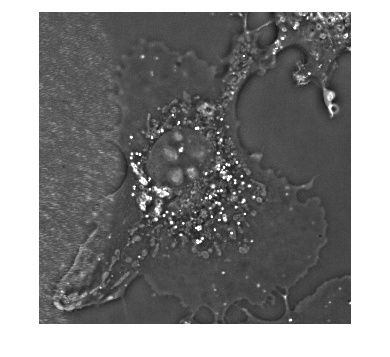

% data anlysis of single cells LDs.
imgSelect = 39;
figure
imshow(Img{1,imgSelect},[3000,15000]);

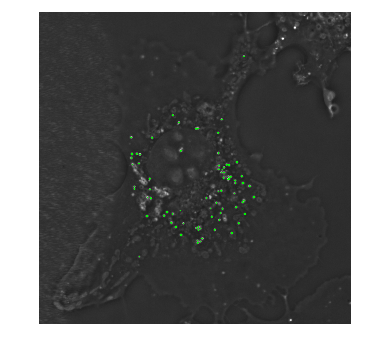


Mask = Img{1,imgSelect};
Mask(:) = 0;
Maskb = Mask;
msize = size(Mask,1);
[xm,ym] = meshgrid(1:msize);

for ii = 1: size(Index1,1)
    if(Index1(ii,11) == imgSelect)
        Mask((xm - Index1(ii,2) - 1.5).^2+(ym - Index1(ii,3) - 2).^2 ...
            <= Index1(ii,5)/3.1415) = 65535;
    end
end

phaseImg = Img{1,imgSelect};
img3 = double(cat(3,phaseImg,phaseImg,phaseImg))/65535;

%%
for ii = 1:msize
    for jj = 1:msize
        if(Mask(ii,jj)~= 0)
            img3(ii,jj,:) = 1*[0,1,0];
        end
    end
end
%%

thres = 0.55;
img3(img3>thres) = thres;
img3 = img3*1/thres;

figure
imshow(img3,[])

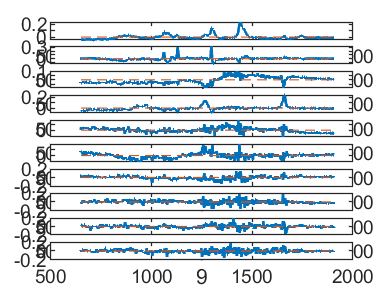


imwrite(img3,'test.tif')
ldsSpecSin = ldsSpec3(Index3(:,11) == imgSelect,:);
IndexSin = Index3(Index3(:,11) == imgSelect,:);

% ldsSpecSin(142,:) = ldsSpecSin(1,:);

[cs,ss,score] = pca(ldsSpecSin);
% figure
% plot(1:163,ss(:,6))
% [score(1)/sum(score)]
% [sum(score(2:5))/sum(score)]

figure
for ii = 1:10
    subplot(10,1,ii)
    plot(wn(x),cs(:,ii + 0),'LineWidth',1.2),xlabel(num2str(ii));
    hold on
    plot(wn(x),zeros(length(x),1),'--','LineWidth',0.5)
end

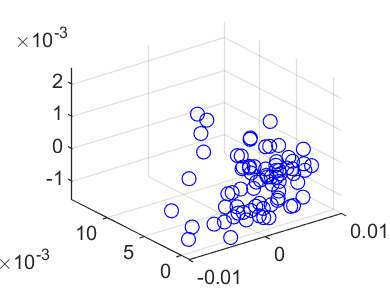


figure
plot3(ss(:,1),ss(:,2),ss(:,3),'bo');
grid on

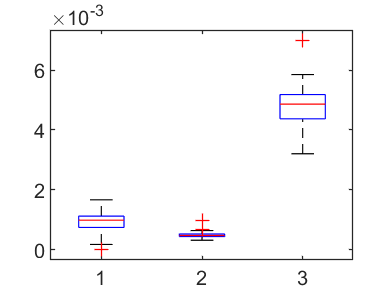


%% 成分差异
PureFAs = [MOA1,MAA1,MPA1,MLA1,MLOA1,mypoly(1,length(x))',-1*mypoly(1,length(x))'];
for ii = 1:size(ldsSpecSin,1)
    xasFAs(ii,:) = lsqnonneg(PureFAs,ldsSpecSin(ii,:)');
end

figure
boxplot(xasFAs(:,1:3));


figure
subplot(2,1,1)
boxplot(xasFAs(IndexSin(:,5)<=median(IndexSin(:,5)),1:5));
mean(xasFAs(IndexSin(:,5)<=median(IndexSin(:,5)),1:5),1)

ans =     0.0009    0.0005    0.0045    0.0003         0


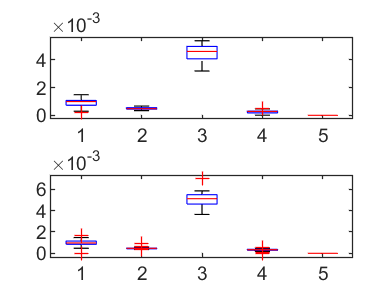

subplot(2,1,2)
boxplot(xasFAs(IndexSin(:,5)>median(IndexSin(:,5)),1:5));

mean(xasFAs(IndexSin(:,5)>median(IndexSin(:,5)),1:5),1)

ans =     0.0010    0.0005    0.0051    0.0003         0


ldsSpecSin = ldsSpec3(Index3(:,11) == imgSelect,:);
IndexSin = Index3(Index3(:,11) == imgSelect,:);

figure
histogram(IndexSin(:,17),16);

figure
for ii = 1:20
    subplot(10,2,ii)
    plot(wn(x),ldsSpecSin(ii,:),'LineWidth',1.2),xlabel(num2str(ii));
end

% ldsSpecSin(71,:) = ldsSpecSin(1,:);

[cs,ss,score] = pca(ldsSpecSin);
figure
for ii = 1:10
    subplot(10,1,ii)
    plot(wn(x),cs(:,ii + 0),'LineWidth',1.2),xlabel(num2str(ii));
    hold on
    plot(wn(x),zeros(length(x),1),'--','LineWidth',0.5)
end

figure
plot3(ss(:,1),ss(:,2),ss(:,3),'bo');
grid on

%% 成分差异
PureFAs = [MOA1,MAA1,MPA1,MLA1,MLOA1,mypoly(1,length(x))',-1*mypoly(1,length(x))'];
for ii = 1:size(ldsSpecSin,1)
    xasFAs(ii,:) = lsqnonneg(PureFAs,ldsSpecSin(ii,:)');
end
figure
boxplot(xasFAs(:,1:5));

figure
plot3(xasFAs(:,1),xasFAs(:,2),xasFAs(:,3),'r.')
grid on;

figure
scatter(xasFAs(1:size(ss,1),2),IndexSin(:,5))

%% 绘制含量分布
Mask1 = double(Mask); Mask1(:) = 0; Mask2 = Mask1; Mask3 = Mask2;

for ii = 1: size(IndexSin, 1)
    for iip = 1:1
        Mask1((xm - IndexSin(ii,2) - 0).^2+(ym - IndexSin(ii,3) - 0).^2 ...
            <= IndexSin(ii,5)/3.1415) = xasFAs(ii,1);
        Mask2((xm - IndexSin(ii,2) - 0).^2+(ym - IndexSin(ii,3) - 0).^2 ...
            <= IndexSin(ii,5)/3.1415) = xasFAs(ii,2);
        Mask3((xm - IndexSin(ii,2) - 0).^2+(ym - IndexSin(ii,3) - 0).^2 ...
            <= IndexSin(ii,5)/3.1415) = xasFAs(ii,3);
    end
end

% Mask1 = (Mask1 - min(Mask1(:)))/(max(Mask1(:)) - min(Mask1(:)));
% Mask2 = (Mask2 - min(Mask2(:)))/(max(Mask2(:)) - min(Mask2(:)));
% Mask3 = (Mask3 - min(Mask3(:)))/(max(Mask3(:)) - min(Mask3(:)));
Mask_m = cat(3,Mask1,Mask2,Mask3);

% figure
% imshow(Mask_m,[])
figure
imshow(Mask1,[])
figure
imshow(Mask2,[])
figure
imshow(Mask3,[])